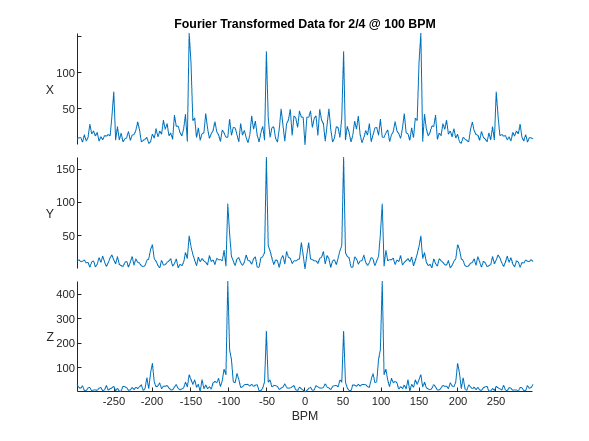

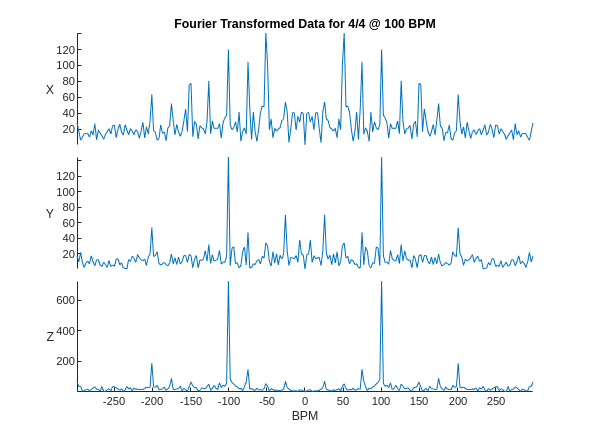

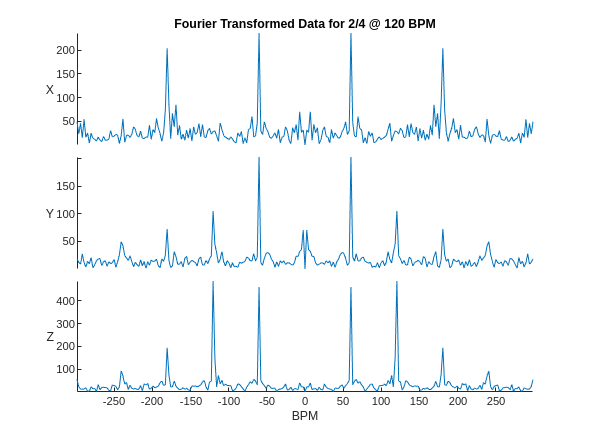

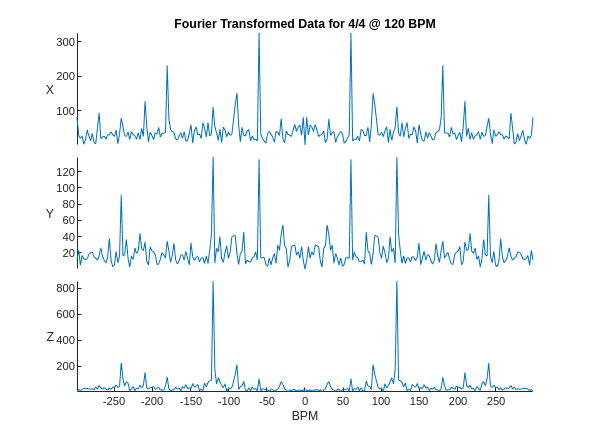

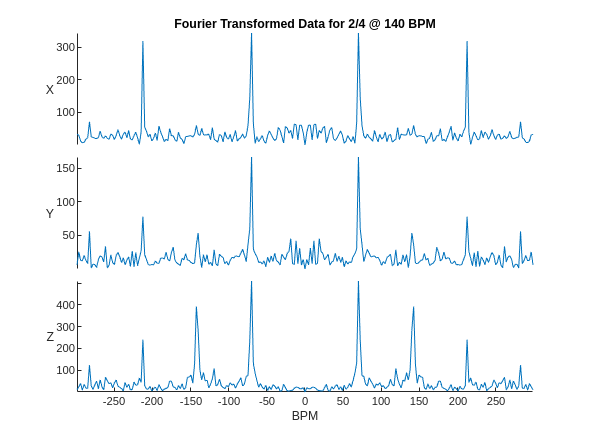

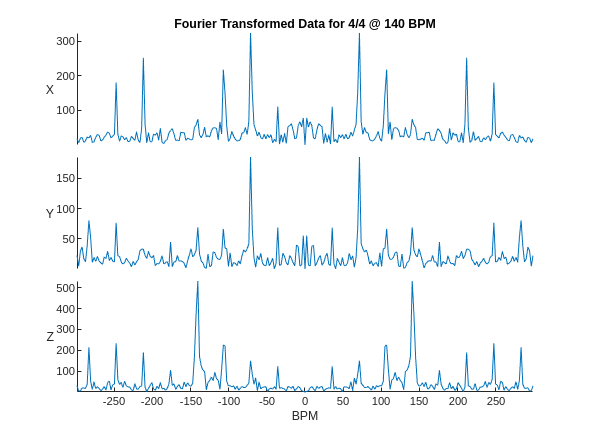

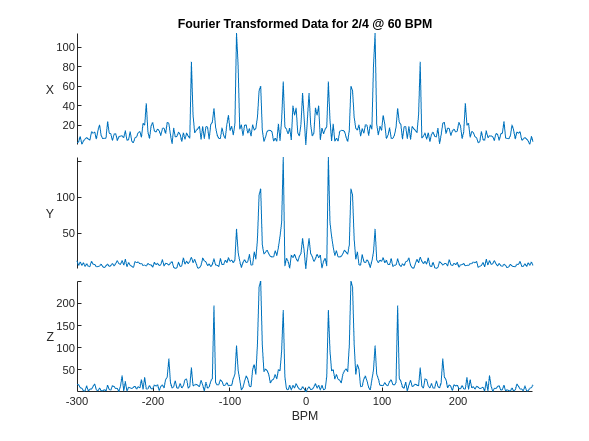

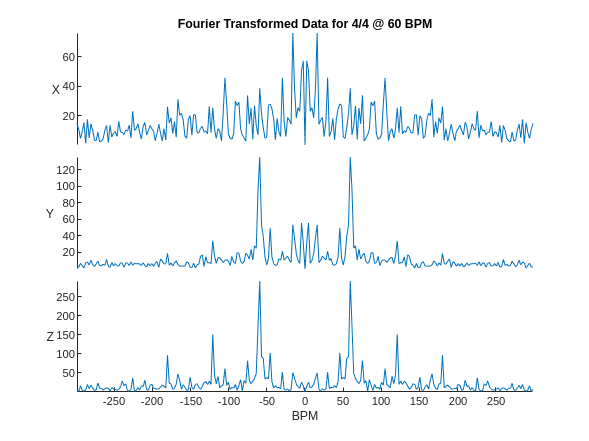

load("all_data.mat");

fields = fieldnames(all_data);
for i = 1:length(fields)    % iterate through each trial
    dataset_title = fields(i);  % get the name of the current trial
    dataset_title = dataset_title{1,1};     % convert name from 1x1 cell to a string
    
    bpm = split(dataset_title, '_');
    bpm = str2double(bpm{2,1});
    
    data_i = all_data.(dataset_title).Acceleration; % get acceleration time table for current trial
    figure;
    [x,y,z] = accelplot(data_i, [3,3]); % plot the data in the time-domain
%     title(sprintf('Accelerometer Data for %s', dataNameToPlotTitle(dataset_title)));
    
    N = length(x);
    Fs = data_i.Properties.SampleRate;
    f = linspace(-Fs/2, Fs/2 - Fs/N, N) + Fs/(2*N)*mod(N, 2);
    xyz = [x,y,z];  % combine xyz into a matrix so it's easy to iterate through
%     [median_, mean_] = medianThing(xyz)
    for xyz_index = 1:3 % fft x, y, and z
        xyz(:,xyz_index) = abs(fftshift(fft(xyz(:,xyz_index))));
    end
%     xyz = xyz(f>=0,:);  % remove magnitudes associated with negative frequencies
%     f_pos = f(f>=0);    % remove negative frequencies from the x axis
    % format everything into a table so stackedplot can work nicely
    xyz_table = table(f', f'.*60, xyz(:,1), xyz(:,2), xyz(:,3), 'VariableNames',{'Frequency (Hz)', 'BPM', 'X', 'Y', 'Z'});
    
    figure;
    stackedplot(xyz_table, {'X', 'Y', 'Z'}, 'XVariable','BPM'); % plot the data in the frequency domain
    title(sprintf('Fourier Transformed Data for %s', dataNameToPlotTitle(dataset_title)));
    
end